## Comparison of R Sqaured and Cointegration Test

clear;
clc;

In a loop, we generate 1000 pair of random series from the normal distribution and calculate the cummulative sum of their sqaure.

Then we compute the R sqaured and test for cointegration using johansen test. Results are saved on two different matrices.

ittr_num = 1000;
r2_matrix = zeros(1, ittr_num);
is_cointegrated = zeros(1, ittr_num);
for i=1:ittr_num
    
    % Generate series
    x = randn(100, 1);
    x2 = cumsum(x.^2);
    y = randn(100, 1);
    y2 = cumsum(y.^2);
    
    % Calculating Oridnary R squared
    mdl = fitlm(x2, y2);
    r2 = mdl.Rsquared.Ordinary;
    r2_matrix(1, i) = r2;
    
    % Testing for cointegration
    [H,pvalue,~,~,mles]=jcitest([x2, y2],'lags',1,'model','H1', 'Display', 'off');
    if H{1,1}==1
        is_cointegrated(1, i) = 1;
    end
end

Plotting the histogram of r2_matrix shows that all values are higher than 85% and the average is above 98%. One could wrongly deduce that two i.i.d series can be used to predict each other or even there is a causality relationship between them; But the cointegration test will reject any relationship between these 1000 pair of series. 

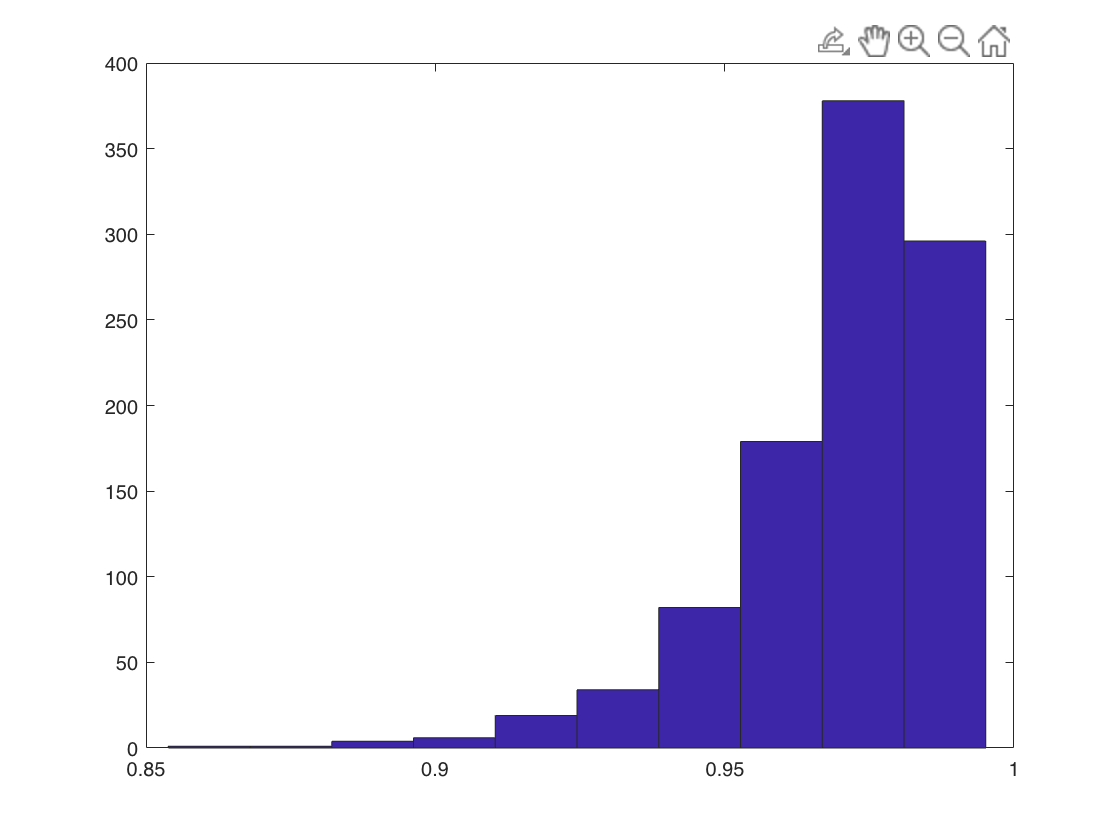

hist(r2_matrix)

Just 59 out of 1000 pair of generated series could pass the cointegration test which indicates that the results obtained from R squared are not reliable for deducting relationship between the two series and other considerations and further investigation should apply while using R squared.

sum(is_cointegrated) 

ans = 59